# Fluxo de carga para redes de distribuição 

- Estrutura radial ou quase radial

- Operação desbalanceada multifásica cm equipamentos  aterrados ou não

- presença de geração dsitribuída

- número de barras e ramos extremamente grandes

O desempenho dos metodos de fluxo de carga desenvolvidos para redes de transmissao pode piorar quando utilizados para análise  de redes de distribuição.

#### Modelo de uma linha de distribuição:

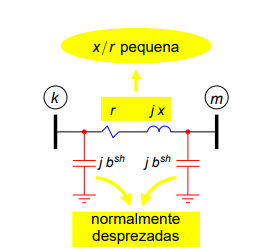

Métodos de eficientes de cálculo de fluxo e carga para redes de distribuição:

- Modificação do método de Newton

- Back-Forward sweep

**Método desacoplado rápido com rotação de eixos: **mudar temporariamente o sistema de referência complexo através da rotação dos eixos real e imaginário de modo que as impedâncias passem a ter relação $\frac{X}{R}$ favorável ao desempenho do MDR

**Método Back-forward sweep:**

- **Arbitrar tensões nodais **$V_k$

- **Calcular corrente nodais **$I_k ={\left(\frac{S_k }{V_k }\right)}^* +Y_k^{\textrm{sh}} V_k$

- **Calcular as correntes nos ramos que conectam os nós k e m **$I_{\textrm{km}} =I_m +\sum I_{\textrm{mj}}$

- **Atualizar as tensões nodais começando pela subestação em direção às barras terminais **$V_m =V_k -Z_{\textrm{km}} I_{\textrm{km}}$

- **Teste de convergencia:  **


$$\max_{k=2,\ldotp \ldotp 4} \left\lbrace \Delta V_k \right\rbrace \le \textrm{tol}\Longrightarrow A\;\textrm{solução}\;\textrm{foi}\;\textrm{obtida}$$
  


$$\max_{k=2,\ldotp \ldotp 4} \left\lbrace \Delta V_k \right\rbrace >\textrm{tol}\Longrightarrow \textrm{Voltar}\;\textrm{ao}\;\textrm{passo}\;2$$
 

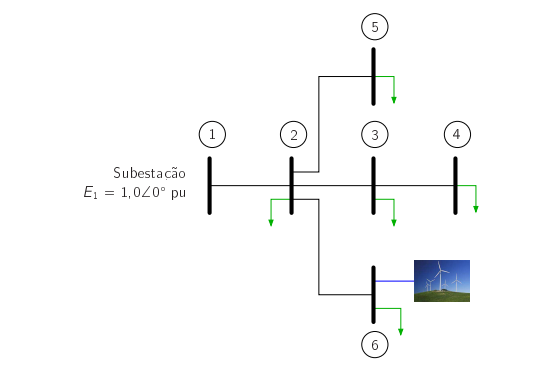

# **Implementação**


% -------------------------------- Q2 Prova --------------------------
%             Env   Rec     Rs[pu]      Xs[pu]  Ysh[pu] Rel_transf_tensao(a)[pu]    Ang_def (rad)

Dados_linha=[ 1      2       0.01      0.005    0.00      1       0;
              2      3       0.06      0.050    0.00      1       0;
              2      4       0.03      0.002    0.00      1       0;
              4      5       0.05      0.002    0.00      1       0;];

%                Barra  Tipo   V      θ      Pi     Qi         Pc      Qc
Dados_barra=[       1     1    1.00   0     0.00    0.00        0.00   0.0;     % Barra 1 tipo 1 → (Vθ) — Barra slack
                    2     3    0.00   0     0.00    0.00        0.50   0.1;     % Barra 2 tipo 3 → (PQ) — Barra de carga
                    3     3    0.00   0     0.00    0.00        1.00   0.6;     % Barra 3 tipo 3 → (PQ) — Barra de carga
                    4     3    0.00   0     0.00    0.00        1.00   0.5;     % Barra 4 tipo 3 → (PQ) — Barra de carga
                    5     3    0.00   0     0.00    0.00        0.80   0.3;];   % Barra 5 tipo 3 → (PQ) — Barra de geração

## 1. Extraindo os dados 

% -------------------------------------------
% Dados da linha de transmissão
% -------------------------------------------
Orig =  Dados_linha(:, 1);
Dest =  Dados_linha(:, 2);
Rs   =  Dados_linha(:, 3);
Xs   =  Dados_linha(:, 4);
bsh  =  Dados_linha(:, 5);
a    =  Dados_linha(:, 6);
phi  =  Dados_linha(:, 7);
NumLT =    size(Orig, 1);

% -------------------------------------------
% Dados da barra
% -------------------------------------------
Barra      = Dados_barra(:, 1);
Tipo       = Dados_barra(:, 2);
Vref       = Dados_barra(:, 3);
Theta      = Dados_barra(:, 4);
Pi         = Dados_barra(:, 5);
Qi         = Dados_barra(:, 6);
Pc         = Dados_barra(:, 7);
Qc         = Dados_barra(:, 8);
NumBarras  = size(Dados_barra, 1);

## 2. Montagem da matriz Y barra

% -------------------------------------------
% (2) Montagem da matriz de admitâncias nodais (Y)
% Considerando linhas com transformadores e admitâncias shunt
% -------------------------------------------

% Inicializa as matrizes de admitâncias
Y = zeros(NumBarras, NumBarras);    % Matriz de admitâncias série das linhas
Ysh = zeros(NumBarras, NumBarras);  % Matriz de admitâncias shunt (susceptâncias)

% -------------------------------------------
% Cálculo das admitâncias série das linhas
% -------------------------------------------
for k = 1:NumLT
    % Admitância série da linha k (recíproco da impedância série)
    y_km = -1 / (Rs(k) + 1i * Xs(k));
    
    % Preenchimento dos termos fora da diagonal da matriz Y
    Y(Orig(k), Dest(k)) = -a(k) * exp(-1i * phi(k)) * y_km;
    Y(Dest(k), Orig(k)) = -a(k) * exp(1i * phi(k)) * y_km;
end

% -------------------------------------------
% Cálculo das admitâncias shunt das linhas
% -------------------------------------------
for k = 1:NumLT
    Ysh(Orig(k), Dest(k)) = -1i * bsh(k);
    Ysh(Dest(k), Orig(k)) = -1i * bsh(k);
end

% -------------------------------------------
% Montagem da matriz de admitâncias nodal completa (YBarra)
% -------------------------------------------
YBarra = -Y;

for k = 1:NumBarras
    % Soma das admitâncias de todas as conexões da barra k
    YBarra(k, k) = -(sum(Ysh(k, :)) - sum(Y(k, :)));
end
Y = YBarra

Y = 1.0e+02 *

   0.8000 - 0.4000i  -0.8000 + 0.4000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.8000 + 0.4000i   1.2302 - 0.5041i  -0.0984 + 0.0820i  -0.3319 + 0.0221i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0984 + 0.0820i   0.0984 - 0.0820i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3319 + 0.0221i   0.0000 + 0.0000i   0.5315 - 0.0301i  -0.1997 + 0.0080i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1997 + 0.0080i   0.1997 - 0.0080i


G = real(Y)

G =    80.0000  -80.0000         0         0         0
  -80.0000  123.0219   -9.8361  -33.1858         0
         0   -9.8361    9.8361         0         0
         0  -33.1858         0   53.1539  -19.9681
         0         0         0  -19.9681   19.9681


B = imag(Y)

B =   -40.0000   40.0000         0         0         0
   40.0000  -50.4091    8.1967    2.2124         0
         0    8.1967   -8.1967         0         0
         0    2.2124         0   -3.0111    0.7987
         0         0         0    0.7987   -0.7987


## 3. Implementação do Algoritmo

%% Potências especificadas nas barras
Pesp = Pi - Pc; % Potência ativa líquida
Qesp = Qi - Qc; % Potência reativa líquida

%% Identificação dos tipos de barras
slack = find(Tipo == 1);
PV = find(Tipo == 2);
PQ = find(Tipo == 3);
barrasPQePV = sort([PQ; PV]);
V = abs(Vref);
V(PQ) = 1;

Tol = 1e-6;
max_iter = 100;
iter = 0;

%% Preparação dos índices
npq = length(PQ);         % Número de barras PQ == L
n = NumBarras;            % Número total de barras
%% --------------------------
% Rotação dos eixos
%% --------------------------

% Cálculo do ângulo médio de rotação
% theta_rot = média dos ângulos dos ramos
% Aqui, como exemplo, adota-se 45 graus (~ ótimo para X/R baixos)
theta_rot = deg2rad(45);

% Rotacionar G e B
G_rot = G * cos(theta_rot) - B * sin(theta_rot);
B_rot = G * sin(theta_rot) + B * cos(theta_rot);

% Rotacionar potências especificadas
Sesp = (Pesp + 1i * Qesp) * exp(1i * theta_rot);
Pesp_rot = real(Sesp);
Qesp_rot = imag(Sesp);

%% Iterações
while true
    iter = iter + 1;

    % ----------------------
    % Potências calculadas
    % ----------------------
    Pcalc = zeros(n,1);
    Qcalc = zeros(n,1);
    for k = 1:n
        for m = 1:n
            ang = Theta(k) - Theta(m);
            Pcalc(k) = Pcalc(k) + V(k)*V(m)*(G_rot(k,m)*cos(ang) + B_rot(k,m)*sin(ang));
            Qcalc(k) = Qcalc(k) + V(k)*V(m)*(G_rot(k,m)*sin(ang) - B_rot(k,m)*cos(ang));
        end
    end

    % ----------------------
    % Mismatch
    % ----------------------
    dP = Pesp_rot - Pcalc;
    dQ = Qesp_rot - Qcalc;
    dQ = dQ(PQ);

    mismatch = [dP(barrasPQePV); dQ];

    fprintf('Iteração %d - Erro máximo = %.8f\n', iter, max(abs(mismatch)));

    if max(abs(mismatch)) < Tol || iter >= max_iter
        fprintf('Convergência atingida em %d iterações.\n', iter);
        break
    end

    % ----------------------
    % Montagem da Jacobiana desacoplada
    % ----------------------

    % H - ∂P/∂θ
    H = zeros(length(barrasPQePV));
    for i = 1:length(barrasPQePV)
        k = barrasPQePV(i);
        for j = 1:length(barrasPQePV)
            m = barrasPQePV(j);
            if k == m
                H(i,j) = -B_rot(k,k);
            else
                H(i,j) = -B_rot(k,m);
            end
        end
    end

    % L - ∂Q/∂V
    L = zeros(npq);
    for i = 1:npq
        k = PQ(i);
        for j = 1:npq
            m = PQ(j);
            if k == m
                L(i,j) = -B_rot(k,k);
            else
                L(i,j) = -B_rot(k,m);
            end
        end
    end

    % ----------------------
    % Solução dos subsistemas
    % ----------------------

    dTheta = H \ dP(barrasPQePV);
    dV = L \ dQ;

    Theta(barrasPQePV) = Theta(barrasPQePV) + dTheta;
    V(PQ) = V(PQ) + dV;
end

Iteração 1 - Erro máximo = 1.13137085
Iteração 2 - Erro máximo = 26.59696660
Iteração 3 - Erro máximo = 357.85762398
Iteração 4 - Erro máximo = 95890.84705899
Iteração 5 - Erro máximo = 430305484.58772904
Iteração 6 - Erro máximo = 20128480675423112.00000000
Iteração 7 - Erro máximo = 52824893536858727862457604243456.00000000
Iteração 8 - Erro máximo = 145425325646631588461750855531548580695657339101145776636559360.00000000
Iteração 9 - Erro máximo = 431433493795230069368681312368205892489799936653007226711155515535982384031984077527776069981517201905708582506656883015680.00000000
Iteração 10 - Erro máximo = 40033860877289915334548756017298871716181912680148011782123909465410700522348162557848390083611422740486951268643530501520573979520133028253665913516984480468796792457120711692888028958046788579614958390816743933602066550912591461922836112736256.00000000
Iteração 11 - Erro máximo = NaN
Iteração 12 - Erro máximo = NaN
Iteração 13 - Erro máximo = NaN
Iteração 14 - Erro máximo = NaN
I

Convergência atingida em 100 iterações.



%% ----------------------
% Desfazendo a rotação para obter resultados finais
%% ----------------------

V_final = V .* exp(1i*Theta);
V_final = V_final .* exp(-1i*theta_rot); % Desfaz rotação

%% ----------------------
% Resultados
%% ----------------------
for k = 1:n
    fprintf('Barra %d: V = %.4f ∠ %.4f graus\n', k, abs(V_final(k)), rad2deg(angle(V_final(k))));
end

Barra 1: V = 1.0000 ∠ -45.0000 graus
Barra 2: V = NaN ∠ NaN graus
Barra 3: V = NaN ∠ NaN graus
Barra 4: V = NaN ∠ NaN graus
Barra 5: V = NaN ∠ NaN graus
